#### 1) At first, we define the mentioned interval and with the step_size = 0.01.

#### then, by moving through the defined interval, the Sinc function will be produced which is can be shown in below.

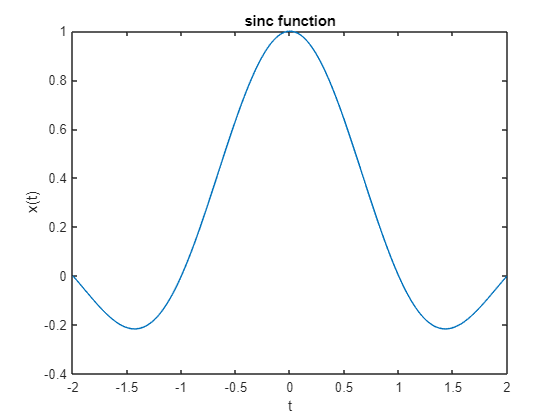

t = -2:0.01:2;

fs1=200; %sampling rate
dt1=1/fs1;  %sampling interval
t1=-2:dt1:2-dt1;
xc_t = sinc(t1);
plot(t1,xc_t);
title('sinc function');
xlabel('t'); ylabel('x(t)');

#### for smapling the signal at 8 Hz frequency, we go through the signal with steps of f_countinuous/f_discrete and we have to define new interval which is f_discrete times bigger than the continuous interval (because of sampling)

f2 = 8;
xd_t = xc_t(1:fs1/f2:length(xc_t));
n_d = (-2*f2):(2*f2);

[comp2, M2] = compressor(xd_t,n_d, 2);

[comp4,M4] = compressor(xd_t,n_d, 4);

### compressor function which is at the end of the live script, takes sample by the rate of M. It also changes the signal's interval by the dactor of 1/M.

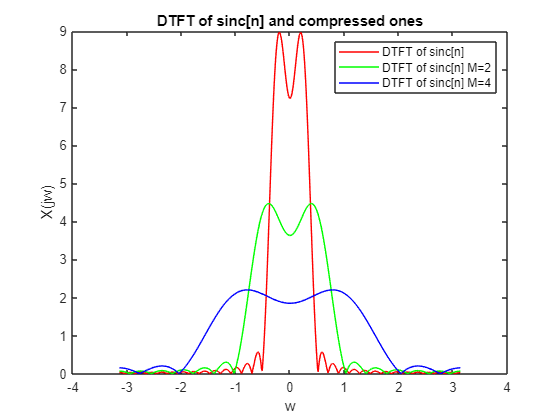

[X_main, w] = dftf_manual(xd_t, n_d);
[X_comp2,w] = dftf_manual(comp2, M2);
[X_comp4,w] = dftf_manual(comp4, M4);
plot(w,abs(X_main),'r',w,abs(X_comp2),'g',w,abs(X_comp4),'b');
title('DTFT of sinc[n] and compressed ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of sinc[n]','DTFT of sinc[n] M=2','DTFT of sinc[n] M=4')

#### As can be seen in figure above, as we compress the signal by different M's, the maximum of signal changes by 1/M factor 

#### and $\omega$  axis will be expanded by factor M.

#### 
$$\sum_{n=0}^M x{\left[nM\right]}e^{-j\omega n} =\frac{1}{M}\sum_{n=0}^M X{\left(j\omega \right)}e^{\frac{j\omega }{M}} e^{-\frac{j\omega 2\pi n}{M}}$$


### 2) for the expander function which is at the end of the live script, we can say it put zeros with the rate of L and it'll go on till reaching the end of the signal. It also changes the signal's interval by the factor of L.

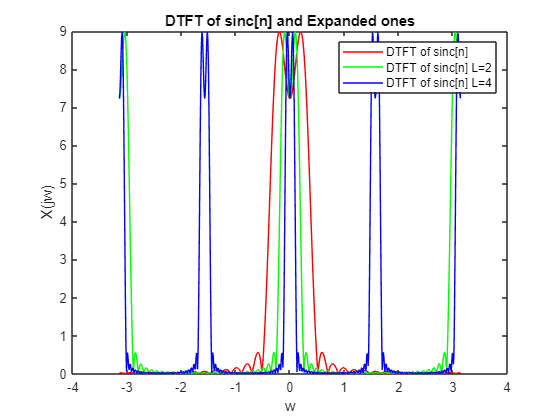

[xd_L2,n_L2] = Expander(xd_t,n_d,2);
[xd_L4,n_L4] = Expander(xd_t,n_d,4);
[X_main, w] = dftf_manual(xd_t, n_d);
[X_exp2,w] = dftf_manual(xd_L2,n_L2);
[X_exp4,w] = dftf_manual(xd_L4,n_L4);
plot(w,abs(X_main),'r',w,abs(X_exp2),'g',w,abs(X_exp4),'b');
title('DTFT of sinc[n] and Expanded ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of sinc[n]','DTFT of sinc[n] L=2','DTFT of sinc[n] L=4')

### As can be seen in figure above, as we increase the L, DTFT of the expanded signal will be shrinked in $\omega
$ axis, but the maximum of signal will be without changes.

#### 
$$\sum_{n=0}^M x{\left[\frac{n}{L}\right]}e^{-j\omega n} =\sum_{n=0}^M x\left\lbrack n\right\rbrack e^{j\omega L} e^{-j\omega n}$$


#### 3) we plot the signal in the mentioned interval ([0,35]) and take the signal as an argument to Compressor function and different M's (2, 4, 8) and will plot the signal in time domain.

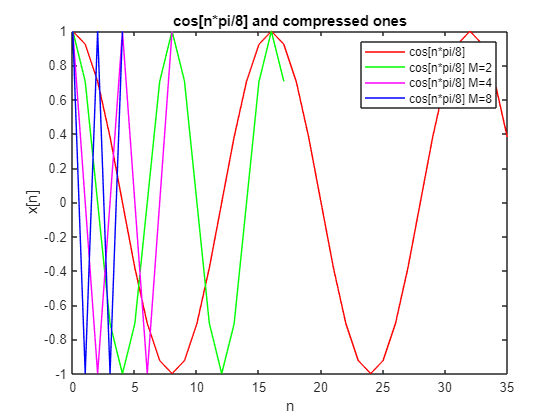

n = 0:1:35;
x_n = cos(n*pi/8);
[compcos1,n1] = compressor(x_n,n, 2);
[compcos2,n2] = compressor(x_n,n, 4);
[compcos3,n3] = compressor(x_n,n, 8);
plot(n,x_n,'r',n1,compcos1,'g',n2,compcos2,'m',n3,compcos3,'b')
title('cos[n*pi/8] and compressed ones')
xlabel('n'); ylabel('x[n]');
legend('cos[n*pi/8]','cos[n*pi/8] M=2','cos[n*pi/8] M=4', 'cos[n*pi/8] M=8')

#### As you can see in Figure above, as we compress the signal by bigger value of M, in time domain, signal will be compressed too.

#### That's because we can say with M = 8, is about zero. It takes one sample in every 8 sample and It occupied little interval.

# 4) interpolators are explained at the end of the live scipt file.

#### Theoretically, we can use all of the four interpolator, but in practice and in real wolrd, implementing sinc function as an ideal block is impossible; because it have non zero values in infinite so we cannot implemente this block ideally.

#### 5) For $\theta =0$, at furst we create intervals and implement cosine function using that interval. We sample the continuous signal with sampling frequency of 40 Hz to get discrete signal. Then we plot them both in one figure to show  how sampling is done.

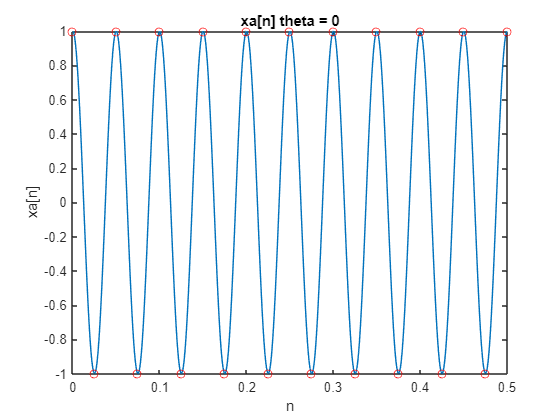

f1 = 1000;
t_5 = 0:1/f1:0.5;
xa_t = cos(40*pi*t_5);

f2 = 40;
xa_n = xa_t(1:f1/f2:length(xa_t));
n = 0:20;
t2_5 = 0:1/f2:0.5;
plot(t_5,xa_t,n/f2,xa_n,'ro')
title('xa[n] theta = 0')
xlabel('n'); ylabel('xa[n]');

#### As you can see, it sampled the maximum and the minimum of the signal.

#### For implementing $\textrm{Cos}\left(40\pi t+\frac{\pi }{6}\right)$ we take actions like the previous one and after sampling the signal, we plot the both to show which part of the signal has been sampled.

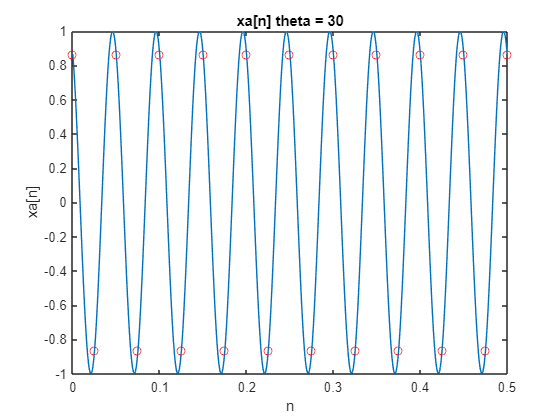

f1 = 1000;
t_5 = 0:1/f1:0.5;
xa_t2 = cos(40*pi*t_5 + pi/6);
f2 = 40;
xa_n2 = xa_t2(1:f1/f2:length(xa_t2));
n = 0:20;
plot(t_5,xa_t2,n/f2,xa_n2,'ro')
title('xa[n] theta = 30')
xlabel('n'); ylabel('xa[n]');

#### As can be seen, sampling points are a little different from maximums and minimums of the signal and that's because of the $\frac{\pi }{6}$ shift in main signal.

#### 
$$\theta =\frac{\pi }{2\;}$$


#### in this signal, we shift it with $\frac{\pi }{2\;}$ so the cosine signal will be converted to $-\textrm{Sin}\left(40\pi t\right)$. With sampling by rate of 40 Hz, we sample zero points of the signal.

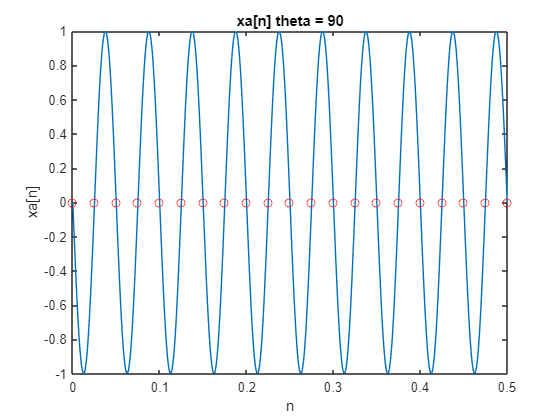

f1 = 1000;
t_5 = 0:1/f1:0.5;
xa_t3 = cos(40*pi*t_5 + pi/2);
f2 = 40;
xa_n3 = xa_t3(1:f1/f2:length(xa_t3));
n = 0:f2/2;
t2_5 = 0:1/f2:0.5;
plot(t_5,xa_t3,t2_5,xa_n3,'ro')
title('xa[n] theta = 90')
xlabel('n'); ylabel('xa[n]');

## `INTERPOLATOR 1: IDEAL INTERPOLATOR`

#### In this part, all of the 3 different signals goes into Expander block to be prepared for entering interpolation block. We start with interpolator $h_1 \left\lbrack n\right\rbrack$. 

#### Expantion coefficient will be 1000/40. And that's beacause the first continuous signal was produced with sampling rate of 1000 Hz and then we change that sampling rate to 40 Hz. so we need 1000/40 = 25 points to take place in between 2 points in signal and get filled.

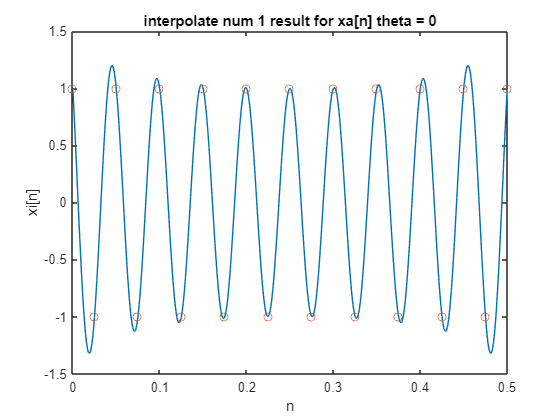

[ex11,nex11] = Expander(xa_n,n,25);
interpolated1_1 = interpolation1(ex11,nex11,25);
plot(t_5,interpolated1_1,n/40,xa_n,'o');
title('interpolate num 1 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

#### $h_1 \left\lbrack n\right\rbrack$ interpolate main signal with acceptable accuracy.

Er0_ideal = immse(interpolated1_1,xa_t)

Er0_ideal = 0.1124

#### The mean squared error of ideal interpolator and the signal with no shift is 0.1124.

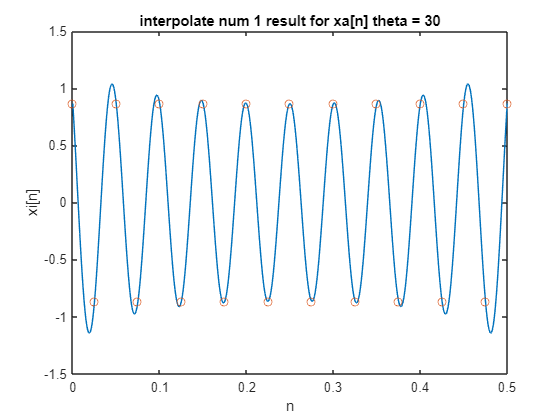

[ex12,nex12] = Expander(xa_n2,n,25);
interpolated2_1 = interpolation1(ex12,nex12,25);
plot(t_5,interpolated2_1,n/40,xa_n2,'o');
title('interpolate num 1 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

#### $h_1 \left\lbrack n\right\rbrack$ interpolate main signal with acceptable accuracy but not as good as the previous one.

Er30_ideal = immse(interpolated2_1,xa_t2)

Er30_ideal = 0.2090

#### The mean squared error of ideal interpolator and the signal with $\frac{\pi }{6}$ shift is 0.2090

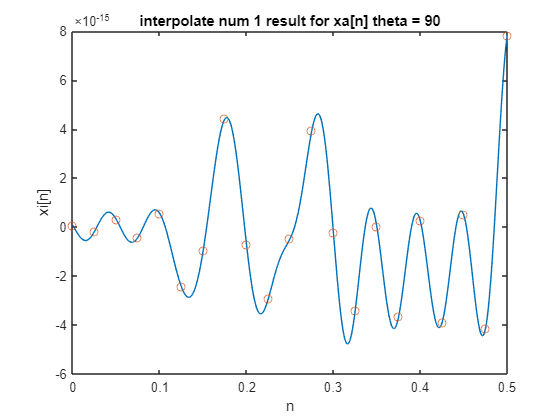

[ex13,nex13] = Expander(xa_n3,n,25);
interpolated3_1 = interpolation1(ex13,nex13,25);
plot(t_5,interpolated3_1,n/40,xa_n3,'o');
title('interpolate num 1 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_ideal = immse(interpolated3_1,xa_t3)

Er90_ideal = 0.4990

#### The main signal cannot be reproduced because we didn't take good and main samples from continous one. Also it can be seen that the Mean squared error of this interpolated signal and main one is high (0.4990).

## `INTERPOLATOR 2: LINEAR INTERPOLATOR`

#### In this part, all of the 3 different signals goes into Expander block to be prepared for entering linear interpolation block .

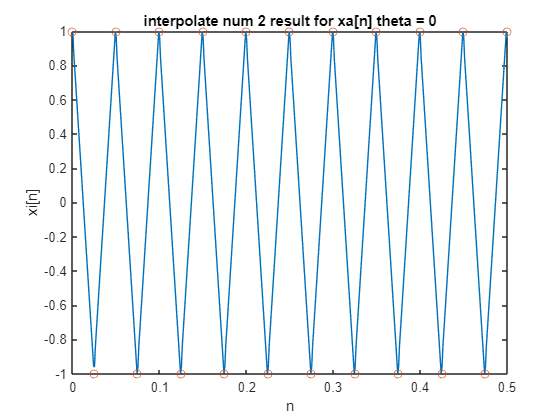

[ex1,nex1] = Expander(xa_n,n,25);
interpolated1_2 = interpolation2(ex1,nex1,25);
plot(t_5,interpolated1_2,n/40,xa_n,'o');
title('interpolate num 2 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

Er0_linear = immse(interpolated1_2,xa_t)

Er0_linear = 0.0287

#### The mean squared error of interpolated signal with no shift and main one is 0.0287 which is smaller that the error for Ideal block.

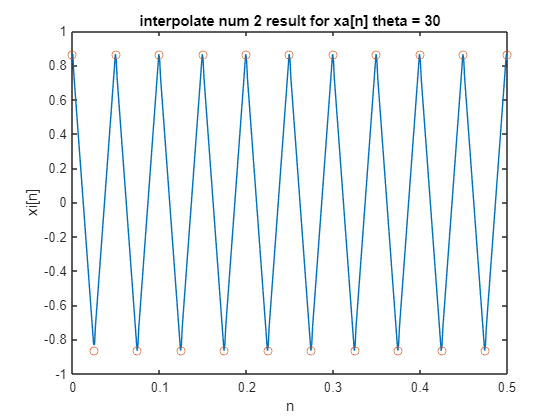

[ex2,nex2] = Expander(xa_n2,n,25);
interpolated2_2 = interpolation2(ex2,nex2,25);
plot(t_5,interpolated2_2,n/40,xa_n2,'o');
title('interpolate num 2 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

Er30_linear = immse(interpolated2_2,xa_t2)

Er30_linear = 0.1034

#### The mean squared error of interpolated signal with $\frac{\pi }{6}$ shift and main one is 0.1034 which is smaller that the error for Ideal block.

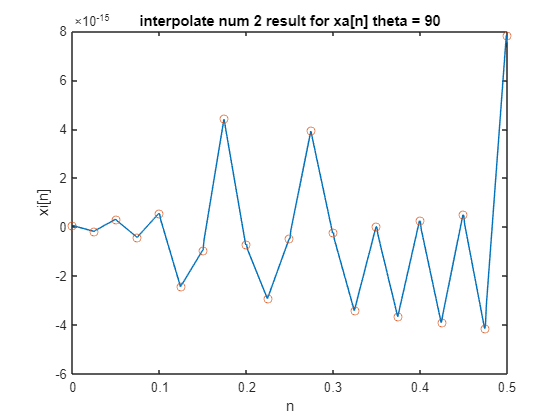

[ex3,nex3] = Expander(xa_n3,n,25);
interpolated3_2 = interpolation2(ex3,nex3,25);
plot(t_5,interpolated3_2,n/40,xa_n3,'o');
title('interpolate num 2 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_linear = immse(interpolated3_2,xa_t3)

Er90_linear = 0.4990

#### It can be seen that the Mean squared error of this interpolated signal with $\frac{\pi }{2}$ shift and main one is high (0.4990) and it's same as MSE of Ideal block.

## `INTERPOLATOR 3: ZERO-ORDER HOLD INTERPOLATOR`

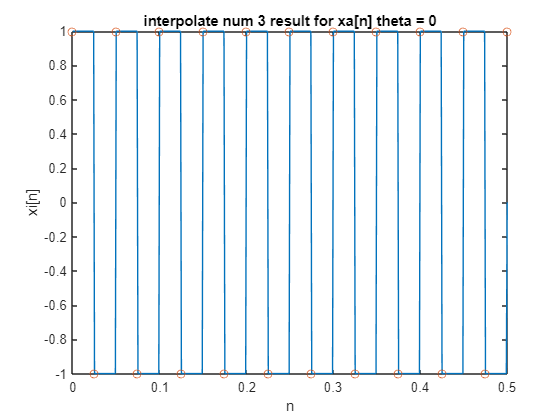

[ex31,nex31] = Expander(xa_n,n,25);
interpolated1_3 = interpolation3(ex31,nex31,25);
plot(t_5,interpolated1_3,n/40,xa_n,'o')
title('interpolate num 3 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

Er0_zoh = immse(interpolated1_3,xa_t)

Er0_zoh = 1.4192

#### Compare to the two previous interpolators, the MSE of this interpolator is high for signal with no shift.

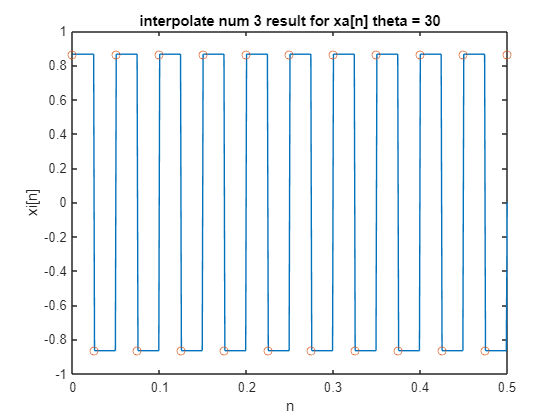

[ex32,nex32] = Expander(xa_n2,n,25);
interpolated2_3 = interpolation3(ex32,nex32,25);
plot(t_5,interpolated2_3,n/40,xa_n2,'o')
title('interpolate num 3 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

Er30_zoh = immse(interpolated2_3,xa_t2)

Er30_zoh = 1.7386

#### It's still higher error tham the previous two interpolator with signal with  $\frac{\pi }{6\;}\;$shift. (1.7386)

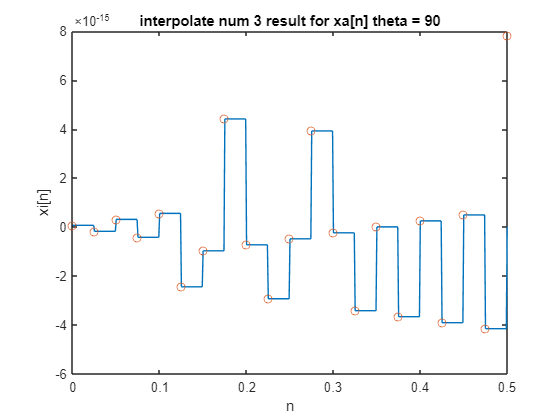

[ex33,nex33] = Expander(xa_n3,n,25);
interpolated3_3 = interpolation3(ex33,nex33,25);
plot(t_5,interpolated3_3,n/40,xa_n3,'o')
title('interpolate num 3 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_zoh = immse(interpolated3_3,xa_t3)

Er90_zoh = 0.4990

## `INTERPOLATOR 4: CUBIC SPLINE INTERPOLATOR`

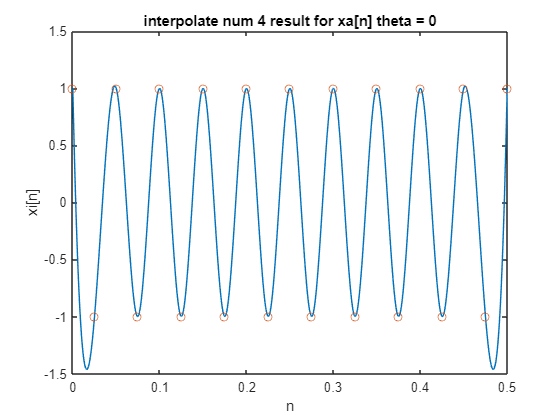

[ex41,nex41] = Expander(xa_n,n,25);
interpolated1_4 = interpolation4(ex41,nex41,40,25);
plot(t_5,interpolated1_4,n/40,xa_n,'o')
title('interpolate num 4 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

Er0_cs = immse(interpolated1_4,xa_t)

Er0_cs = 0.1130

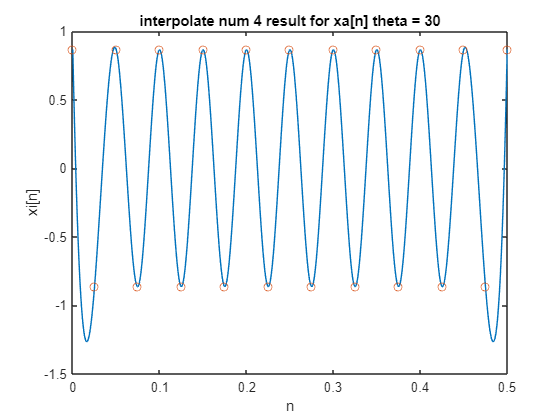

[ex42,nex42] = Expander(xa_n2,n,25);
interpolated2_4 = interpolation4(ex42,nex42,40,25);
plot(t_5,interpolated2_4,n/40,xa_n2,'o')
title('interpolate num 4 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

Er30_cs = immse(interpolated2_4,xa_t2)

Er30_cs = 0.2095

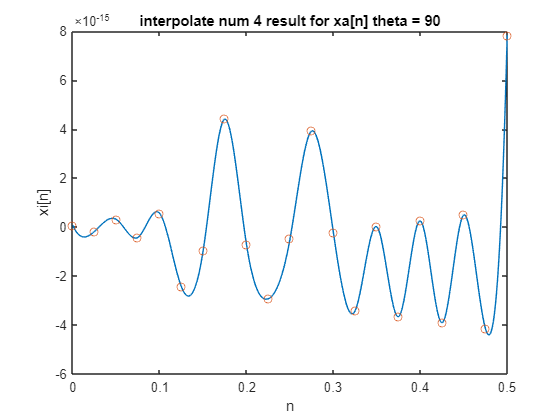

[ex43,nex43] = Expander(xa_n3,n,25);
interpolated3_4 = interpolation4(ex43,nex43,40,25);
plot(t_5,interpolated3_4,n/40,xa_n3,'o')
title('interpolate num 4 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_cs = immse(interpolated3_4,xa_t3)

Er90_cs = 0.4990

#### $\theta =0$:

#### Ideal MSE = 0.1124

#### Linear MSE = 0.287

#### ZO hold MSE = 1.4192

#### Cubic spline MSE = 0.1130

#### $\theta =\frac{\pi }{6}$:

#### Ideal MSE = 0.2090

#### Linear MSE = 0.1034

#### ZO hold MSE = 1.7386

#### Cubic spline MSE = 0.2095

#### $\theta =\frac{\pi }{2}$:

#### Ideal MSE = 0.4990

#### Linear MSE = 0.4990

#### ZO hold MSE = 0.4990

#### Cubic spline MSE = 0.4990

### As can be seen, the Ideal interpolator and cubic spline interpolators have the lowest errors among these three interpolators and have the most smooth results.

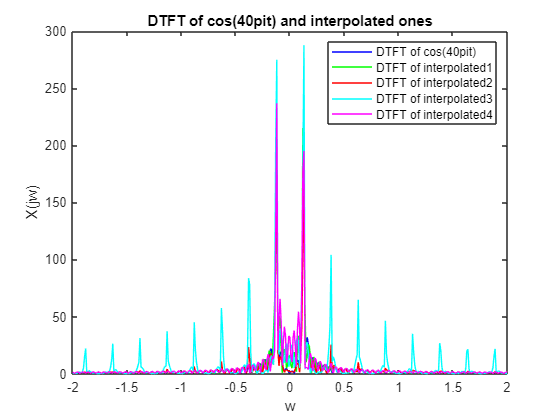

n_ad = 0:0.5*f1;
[X0_main, w] = dftf_manual(xa_t, n_ad);
[X0_inter1,w] = dftf_manual(interpolated1_1,n_ad);
[X0_inter2,w] = dftf_manual(interpolated1_2,n_ad);
[X0_inter3,w] = dftf_manual(interpolated1_3,n_ad);
[X0_inter4,w] = dftf_manual(interpolated1_4,n_ad);
plot(w,abs(X0_main),'b',w,abs(X0_inter1),'g',w,abs(X0_inter2),'r',w,abs(X0_inter3),'c',w,abs(X0_inter4),'m');
title('DTFT of cos(40pit) and interpolated ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of cos(40pit)','DTFT of interpolated1','DTFT of interpolated2','DTFT of interpolated3', 'DTFT of interpolated4')
ax = gca;
ax.XLim = [-2 2];

#### We can see in figure above that the DTFT of Cos(40*pi*t) is symmetric and there are two kinds of impulses at $\omega
$ = 0.02 but in different interpolators, it will be appeared in asymmetric way. the best symmetric ones are the interpolated with cubic spline and ideal interpolater.

#### There is another point that have to be mentioned about the repetation of the impulses and the reason for that is we cannot reproduce the exact Cosine-type function. So it's not only have 2 impulses.

#### The other results of interpolating is having noise in frequency domain. As you can see, the interpolator num3 create the most noises in the DTFT of signal.

#### The nearest DTFTs to the DTFT of signal are results from interpolator 4 (cubic spline) and interpolator 1 (Ideal).

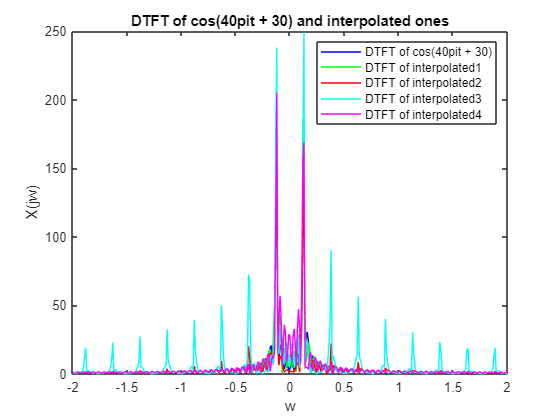

n_ad = 0:0.5*f1;
[X30_main, w] = dftf_manual(xa_t2, n_ad);
[X30_inter1,w] = dftf_manual(interpolated2_1,n_ad);
[X30_inter2,w] = dftf_manual(interpolated2_2,n_ad);
[X30_inter3,w] = dftf_manual(interpolated2_3,n_ad);
[X30_inter4,w] = dftf_manual(interpolated2_4,n_ad);
plot(w,abs(X30_main),'b',w,abs(X30_inter1),'g',w,abs(X30_inter2),'r',w,abs(X30_inter3),'c',w,abs(X30_inter4),'m');
title('DTFT of cos(40pit + 30) and interpolated ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of cos(40pit + 30)','DTFT of interpolated1','DTFT of interpolated2','DTFT of interpolated3', 'DTFT of interpolated4')
ax = gca;
ax.XLim = [-2 2];

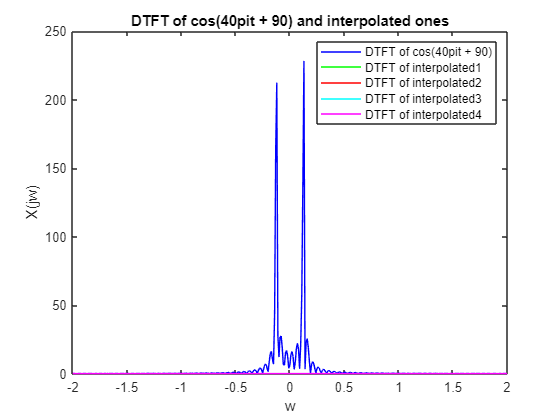

n_ad = 0:0.5*f1;
[X90_main, w] = dftf_manual(xa_t3, n_ad);
[X90_inter1,w] = dftf_manual(interpolated3_1,n_ad);
[X90_inter2,w] = dftf_manual(interpolated3_2,n_ad);
[X90_inter3,w] = dftf_manual(interpolated3_3,n_ad);
[X90_inter4,w] = dftf_manual(interpolated3_4,n_ad);
plot(w,abs(X90_main),'b',w,abs(X90_inter1),'g',w,abs(X90_inter2),'r',w,abs(X90_inter3),'c',w,abs(X90_inter4),'m');
title('DTFT of cos(40pit + 90) and interpolated ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of cos(40pit + 90)','DTFT of interpolated1','DTFT of interpolated2','DTFT of interpolated3', 'DTFT of interpolated4')
ax = gca;
ax.XLim = [-2 2];

#### As we can see in figure above, the DTFT of interpolated signals are about zero. The reason of that is the sampling rate for converting continuous signal to discrete signal, is below the nyquist rate and also because of the high amount of shifting, only takes the samples that had zero values. So the main signal cannot be reconstruct. It can be concluded that shifting the main signal is effective in reproducing the signal.